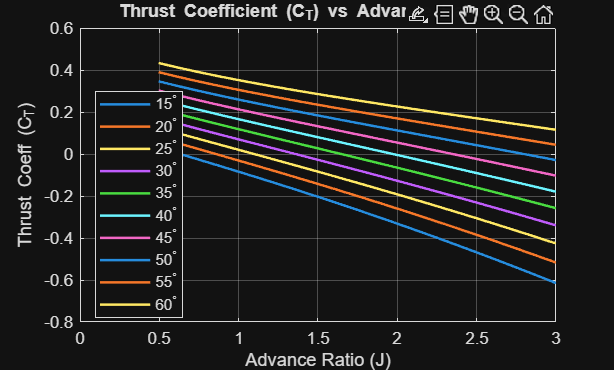

clear; clc; close all;

%% 1. Setup and Parameters
% Environment and Geometry
rho = 1.22;                 % Air density (kg/m^3)
c = 0.1;                    % Chord (m) - constant
D = 3;                      % Diameter (m)
R = D / 2;                  % Radius (m)
B = 3;                      % Number of blades
n_rpm = 1300;               % Rotational speed (RPM)
n = n_rpm / 60;             % Rotational speed (rev/s)
omega = n * 2 * pi;         % Angular velocity (rad/s)

% Velocity Range
V_kmh = 116:2:702;          % Velocity range 116 to 702 km/hr
V_ms = V_kmh ./ 3.6;        % Convert to m/s

% Pitch Angles at 0.75R
beta_angles_deg = [15, 20, 25, 30, 35, 40, 45, 50, 55, 60];

% Discretize the blade (Blade Element Theory)
% Integrating from 0.15R (hub approximation) to R
N_elements = 100;
r = linspace(0.15*R, R, N_elements); 
dr = r(2) - r(1);

%% 2. Main Computation Loop
% Pre-allocate arrays for results
CT_all = zeros(length(beta_angles_deg), length(V_ms));
CQ_all = zeros(length(beta_angles_deg), length(V_ms));
CP_all = zeros(length(beta_angles_deg), length(V_ms));
Eta_all = zeros(length(beta_angles_deg), length(V_ms));
J_arr = V_ms ./ (n * D); % Advance Ratio J

for i = 1:length(beta_angles_deg)
    beta_ref = beta_angles_deg(i);
    
    for j = 1:length(V_ms)
        V = V_ms(j);
        
        % --- Blade Element Integration ---
        dT_sum = 0;
        dQ_sum = 0;
        
        for k = 1:length(r)
            rk = r(k);
            
            % 1. Local Pitch (Beta) Calculation
            % Assumption: Constant Geometric Pitch distribution implies:
            % r * tan(beta) = const. We calculate const using r=0.75R.
            beta_rad = atan((0.75 * R / rk) * tand(beta_ref));
            
            % 2. Flow Angle (Phi)
            % W = resultant velocity
            phi_rad = atan(V / (omega * rk));
            W = sqrt(V^2 + (omega * rk)^2);
            
            % 3. Angle of Attack (Alpha)
            alpha_rad = beta_rad - phi_rad;
            % Note: CL formula uses alpha in degrees, but we used radians * 6.2
            % The prompt says CL = 6.2 * alpha * pi / 180. 
            % Since alpha_rad = alpha_deg * pi / 180, this is simply CL = 6.2 * alpha_rad.
            CL = 6.2 * alpha_rad; 
            CD = 0.008 - 0.003 * CL + 0.01 * CL^2;
            
            % 5. Forces
            % Lift and Drag per unit span
            dL = 0.5 * rho * W^2 * c * CL;
            dD = 0.5 * rho * W^2 * c * CD;
            
            % Thrust and Torque components per blade
            dT_elem = dL * cos(phi_rad) - dD * sin(phi_rad);
            dQ_elem = (dL * sin(phi_rad) + dD * cos(phi_rad)) * rk;
            
            % Integration Sum
            dT_sum = dT_sum + dT_elem * dr;
            dQ_sum = dQ_sum + dQ_elem * dr;
        end
        
        % Total Thrust and Torque (x Number of Blades)
        T = dT_sum * B;
        Q = dQ_sum * B;
        
        % Coefficients
        CT_all(i, j) = T / (rho * n^2 * D^4);
        CQ_all(i, j) = Q / (rho * n^2 * D^5);
        CP_all(i, j) = 2 * pi * CQ_all(i, j);
        
        % Efficiency
        % Protect against divide by zero at V=0
        if CP_all(i, j) > 0
            Eta_all(i, j) = J_arr(j) * CT_all(i, j) / CP_all(i, j);
        else
            Eta_all(i, j) = 0;
        end
    end
end

%% 3. Task 2 & 3: Plotting CT, CQ, CP, Efficiency vs J
% Now plotting in separate figures for better visibility

% --- Figure 1: Thrust Coefficient ---
figure('Name', 'Thrust Coefficient (CT)');
plot(J_arr, CT_all, 'LineWidth', 1.5);
xlabel('Advance Ratio (J)'); ylabel('Thrust Coeff (C_T)');
title('Thrust Coefficient (C_T) vs Advance Ratio (J)'); 
grid on;
legend(string(beta_angles_deg) + "^\circ", 'Location', 'best');

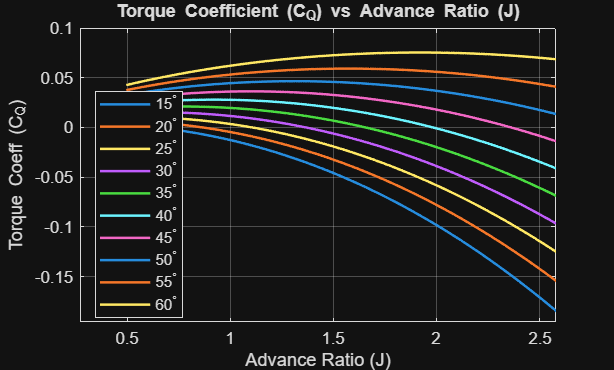


% --- Figure 2: Torque Coefficient ---
figure('Name', 'Torque Coefficient (CQ)');
plot(J_arr, CQ_all, 'LineWidth', 1.5);
xlabel('Advance Ratio (J)'); ylabel('Torque Coeff (C_Q)');
title('Torque Coefficient (C_Q) vs Advance Ratio (J)'); 
grid on;
legend(string(beta_angles_deg) + "^\circ", 'Location', 'best');

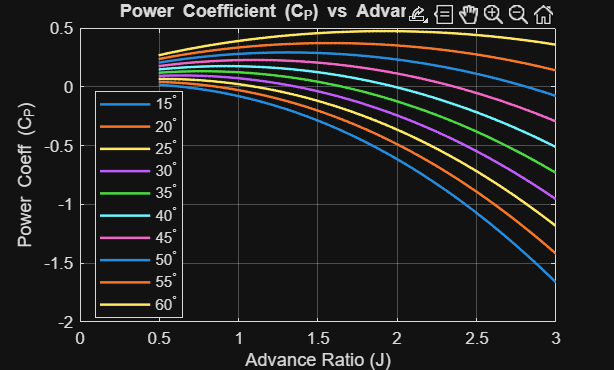


% --- Figure 3: Power Coefficient ---
figure('Name', 'Power Coefficient (CP)');
plot(J_arr, CP_all, 'LineWidth', 1.5);
xlabel('Advance Ratio (J)'); ylabel('Power Coeff (C_P)');
title('Power Coefficient (C_P) vs Advance Ratio (J)'); 
grid on;
legend(string(beta_angles_deg) + "^\circ", 'Location', 'best');

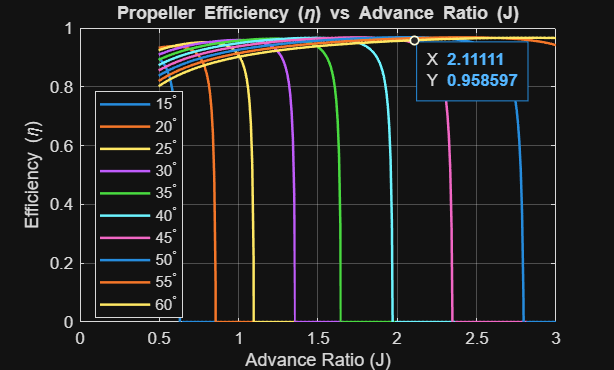


% --- Figure 4: Efficiency ---
figure('Name', 'Propeller Efficiency');
plot(J_arr, Eta_all, 'LineWidth', 1.5);
xlabel('Advance Ratio (J)'); ylabel('Efficiency (\eta)');
title('Propeller Efficiency (\eta) vs Advance Ratio (J)'); 
grid on;
ylim([0 1]);
legend(string(beta_angles_deg) + "^\circ", 'Location', 'best');

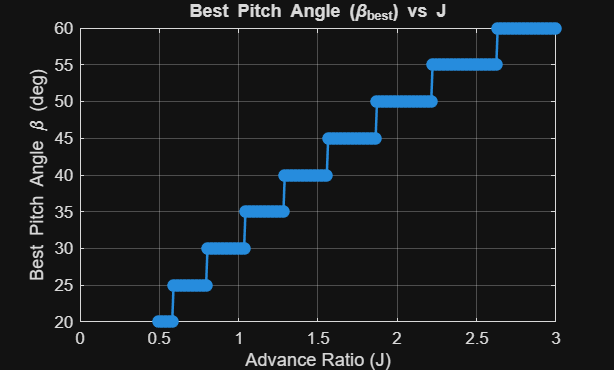


%% 4. Task 4: Determine Best Blade Pitch Angle vs J

best_beta_indices = zeros(1, length(J_arr));
best_beta_vals = zeros(1, length(J_arr));

for j = 1:length(J_arr)
    % Find index of max efficiency for this specific J
    [~, idx] = max(Eta_all(:, j));
    best_beta_indices(j) = idx;
    best_beta_vals(j) = beta_angles_deg(idx);
end

% --- Figure 5: Best Pitch Angle ---
figure('Name', 'Best Pitch Angle');
plot(J_arr, best_beta_vals, '-o', 'LineWidth', 1.5);
xlabel('Advance Ratio (J)');
ylabel('Best Pitch Angle \beta (deg)');
title('Best Pitch Angle (\beta_{best}) vs J');
grid on;

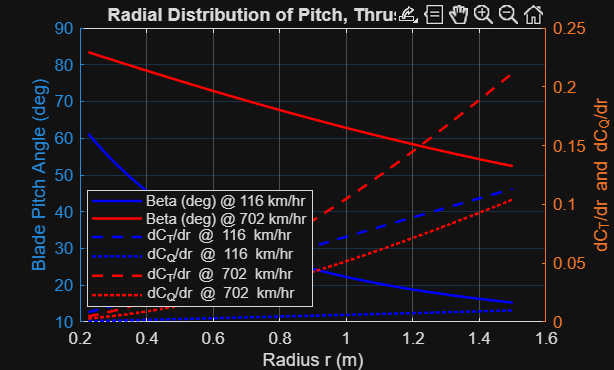


%% 5. Task 5 (Extra Credit): Derivatives for 116 and 702 km/hr

% Find J indices for specific velocities
[~, idx_116] = min(abs(V_kmh - 116));
[~, idx_702] = min(abs(V_kmh - 702));

target_indices = [idx_116, idx_702];
target_V_labels = ["116 km/hr", "702 km/hr"];

% --- Figure 6: Radial Distributions ---
figure('Name', 'Extra Credit: Radial Distributions');

colors = ['b', 'r']; % Color for each velocity case

for i = 1:length(target_indices)
    idx_v = target_indices(i);
    V = V_ms(idx_v);
    
    % Get the best beta determined in Task 4 for this velocity
    best_beta_idx = best_beta_indices(idx_v);
    beta_ref = beta_angles_deg(best_beta_idx);
    
    % Re-calculate distribution for this specific case
    beta_dist_deg = zeros(size(r));
    dCT_dr = zeros(size(r));
    dCQ_dr = zeros(size(r));
    
    for k = 1:length(r)
        rk = r(k);
        beta_rad = atan((0.75 * R / rk) * tand(beta_ref));
        beta_dist_deg(k) = rad2deg(beta_rad);
        
        phi_rad = atan(V / (omega * rk));
        W = sqrt(V^2 + (omega * rk)^2);
        alpha_rad = beta_rad - phi_rad;
        
        CL = 6.2 * alpha_rad;
        CD = 0.008 - 0.003 * CL + 0.01 * CL^2;
        
        dL = 0.5 * rho * W^2 * c * CL;
        dD = 0.5 * rho * W^2 * c * CD;
        
        dT = dL * cos(phi_rad) - dD * sin(phi_rad);
        dQ = (dL * sin(phi_rad) + dD * cos(phi_rad)) * rk;
        
        % Normalize to get dCT/dr and dCQ/dr
        dCT_dr(k) = (dT * B) / (rho * n^2 * D^4);
        dCQ_dr(k) = (dQ * B) / (rho * n^2 * D^5);
    end
    
    % Plotting
    yyaxis left
    plot(r, beta_dist_deg, [colors(i) '-'], 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Beta (deg) @ %s', target_V_labels(i)));
    ylabel('Blade Pitch Angle (deg)');
    hold on;
    
    yyaxis right
    plot(r, dCT_dr, [colors(i) '--'], 'LineWidth', 1.5, ...
        'DisplayName', sprintf('dC_T/dr @ %s', target_V_labels(i)));
    hold on;
    plot(r, dCQ_dr, [colors(i) ':'], 'LineWidth', 1.5, ...
        'DisplayName', sprintf('dC_Q/dr @ %s', target_V_labels(i)));
    ylabel('dC_T/dr and dC_Q/dr');
end

xlabel('Radius r (m)');
title('Radial Distribution of Pitch, Thrust, and Torque');
legend('Location', 'best');
grid on;